# General linear system identifier

Hc = tf(2, [0.7 1]);
Ts = 0.1;
Hd = c2d(Hc, Ts, 'zoh')

Hd =
 
    0.2662
  ----------
  z - 0.8669
 
Sample time: 0.1 seconds
Discrete-time transfer function.



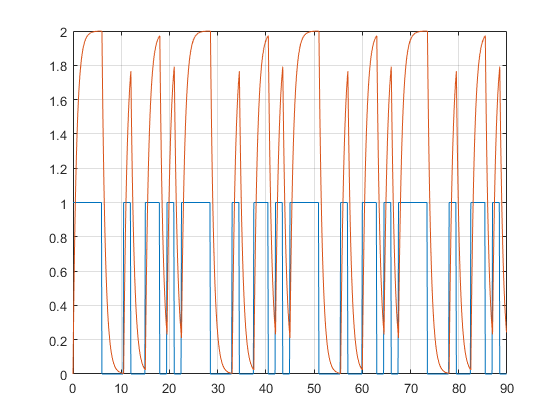


[u, t] = SPAB_GEN(4, 3, 4, Ts, 15, 4);
[num, den] = tfdata(Hd, 'v');
y = dlsim(num, den, u);
%y = y + normrnd(0, 0.05, [length(y) 1]);

na = 1;
nb = 0;
nd = 1;
figure, 
plot(t, [u' y]); grid;


theta = 2*rand([na + 1 + nb, 1]) - 1;
theta = [theta zeros(na + 1 + nb, 1)];

phi = zeros(na + nb + 1, length(y));
for i = 1:nb+1
    phi(i, (nd + i):end) = u(1:end-nd-i+1);
end
k = nb + 2;
for i = 1:na
    phi(k, i + 1:end) = -y(1:end - i);
    k = k + 1;
end

phi = [u; -y'];

evalGradient = @(theta, phi, y)(-2*sum((y - theta'*phi).*phi, 2));
evalHessian = @(phi)(2*phi*phi');
evalCost = @(theta, phi, y)(sum((y - theta'*phi).^2));
step = 0.01;
stepUpperThreshold = 10000;
stepBottomTreshold = 0.000001;
beta = 1.1;

tic
for i = 3:length(t)
    gradient = evalGradient(theta(:, 1), phi(:, 1:i - 1), y(2:i)');
    gradient = gradient/norm(gradient);
    hessian = evalHessian(phi(:, 1:i - 1));
    hessian = hessian/norm(hessian);
   
    theta(:, 2) = theta(:, 1) - hessian\gradient*step;
    cost = evalCost(theta(:, 2), phi(:, 1:i - 1), y(2:i)');
    newStep = beta*step;
    theta(:, 2) = theta(:, 1) - hessian\gradient*newStep;
    newCost = evalCost(theta(:, 2), phi(:, 1:i - 1), y(2:i)');
    
    if newCost < cost
        while newCost < cost && newStep < stepUpperThreshold
            cost = newCost;
            newStep = beta*newStep;
            theta(:, 2) = theta(:, 1) - hessian\gradient*newStep;
            newCost = evalCost(theta(:, 2), phi(:, 1:i - 1), y(2:i)');
        end
        newStep = newStep/beta;
        theta(:, 2) = theta(:, 1) - hessian\gradient*newStep;
    else
        newStep = step/beta;
        theta(:, 2) = theta(:, 1) - hessian\gradient*newStep;
        newCost = evalCost(theta(:, 2), phi(:, 1:i - 1), y(2:i)');
        
        if newCost < cost 
            while newCost < cost && newStep > stepBottomTreshold
                cost = newCost;
                newStep = newStep/beta;
                theta(:, 2) = theta(:, 1) - hessian\gradient*newStep;
                newCost = evalCost(theta(:, 2), phi(:, 1:i - 1), y(2:i)');
            end
            newStep = newStep*beta;
            theta(:, 2) = theta(:, 1) - hessian\gradient*newStep;
        else
            theta(:, 2) = theta(:, 1) - hessian\gradient*step;
        end
    end
    
    theta(:, 1) = theta(:, 2);
    
%     gradient = evalGradient(theta2(:, 1), phi(:, 1:i - 1), y(2:i)');
%     gradient = gradient/norm(gradient);
%     hessian = evalHessian1(phi(:, 1:i - 1));
%     hessian = hessian/norm(hessian);
%     
%     theta2(:, 2) = theta2(:, 1) - hessian\gradient*step;
%     theta2(:, 1) = theta2(:, 2);
end
toc

Elapsed time is 1.175875 seconds.


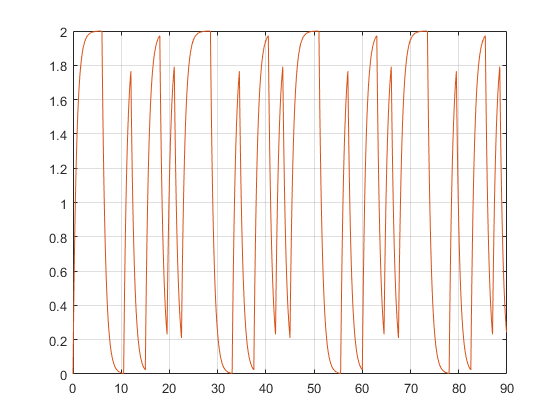


Hid = tf(theta(1, 1), [1 theta(2, 1)], Ts);
[num, den] = tfdata(Hid, 'v');
ys = dlsim(num, den, u);
figure, 
plot(t, [y, ys]); grid;

Hc = tf([-5 12], [1 1.3 10]);

Ts = 0.1;
Hd = c2d(Hc, Ts, 'zoh')

Hd =
 
    -0.4041 z + 0.5157
  ----------------------
  z^2 - 1.785 z + 0.8781
 
Sample time: 0.1 seconds
Discrete-time transfer function.



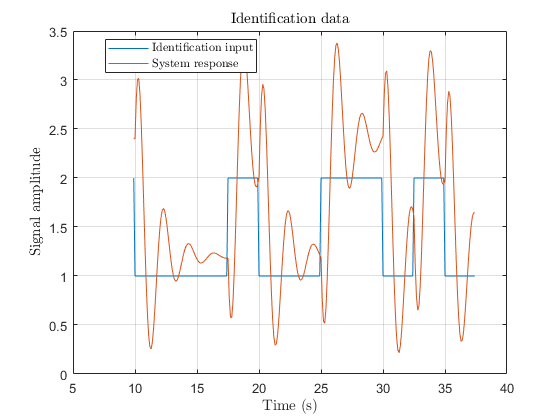


[u, t] = SPAB_GEN(4, 3, 4, Ts, 25, 1);
u = u + 1;
[num, den] = tfdata(Hd, 'v');
y = dlsim(num, den, u);
%y = y + normrnd(0, 0.01, [length(y) 1]);
u = u(100:end);
t = t(100:end);
y = y(100:end);

na = 2;
nb = 1;
nd = 1;
figure, 
plot(t, [u' y]); grid;
title('Identification data', 'Interpreter', 'latex');
xlabel('Time (s)', 'Interpreter', 'Latex');
ylabel('Signal amplitude', 'Interpreter', 'Latex');
legend('Identification input', 'System response', 'Interpreter', 'Latex', 'Location',"best");


theta = 2*rand([na + 1 + nb, 1]) - 1;
theta = [theta zeros(na + 1 + nb, 1)];

phi = zeros(na + nb + 1, length(y));
for i = 1:nb+1
    phi(i, (nd + i):end) = u(1:end-nd-i+1);
end
k = nb + 2;
for i = 1:na
    phi(k, i + 1:end) = -y(1:end - i);
    k = k + 1;
end
phi = phi(:, 3:end);
y = y(3:end);

evalGradient = @(theta, phi, y)(-2*sum((y - theta'*phi).*phi, 2));
evalHessian = @(phi)(2*phi*phi');
evalCost = @(theta, phi, y)(sum((y - theta'*phi).^2));
step = 1;
stepUpperThreshold = 100000;
stepBottomTreshold = 0.000001;
beta = 1.1;

tic
for i = na + nb + 2:length(t)-2
    gradient = evalGradient(theta(:, 1), phi(:, 1:i), y(1:i)');
    gradient = gradient/norm(gradient);
    hessian = evalHessian(phi(:, 1:i));
    hessian = hessian/norm(hessian);
   
    theta(:, 2) = theta(:, 1) - hessian\gradient*step;
    cost = evalCost(theta(:, 2), phi(:, 1:i), y(1:i)');
    newStep = beta*step;
    theta(:, 2) = theta(:, 1) - hessian\gradient*newStep;
    newCost = evalCost(theta(:, 2), phi(:, 1:i), y(1:i)');
    
    if newCost < cost
        while newCost < cost && newStep < stepUpperThreshold
            cost = newCost;
            newStep = beta*newStep;
            theta(:, 2) = theta(:, 1) - hessian\gradient*newStep;
            newCost = evalCost(theta(:, 2), phi(:, 1:i), y(1:i)');
        end
        newStep = newStep/beta;
        theta(:, 2) = theta(:, 1) - hessian\gradient*newStep;
    else
        newStep = step/beta;
        theta(:, 2) = theta(:, 1) - hessian\gradient*newStep;
        newCost = evalCost(theta(:, 2), phi(:, 1:i), y(1:i)');
        
        if newCost < cost 
            while newCost < cost && newStep > stepBottomTreshold
                cost = newCost;
                newStep = newStep/beta;
                theta(:, 2) = theta(:, 1) - hessian\gradient*newStep;
                newCost = evalCost(theta(:, 2), phi(:, 1:i), y(1:i)');
            end
            newStep = newStep*beta;
            theta(:, 2) = theta(:, 1) - hessian\gradient*newStep;
        else
            theta(:, 2) = theta(:, 1) - hessian\gradient*step;
        end
    end
    theta(:, 1) = theta(:, 2);
end
toc

Elapsed time is 0.439874 seconds.



Hid = tf(theta(1:nb+1, 1)', [1 theta(nb+2:nb+1+na, 1)'], Ts);
[num, den] = tfdata(Hid, 'v');
ys = dlsim(num, den, u);
figure, 
plot(t, y); grid;

Error using plot
Vectors must be the same length.

hold on;
plot(t, ys)
title('Model evaluation', 'Interpreter', 'latex');
xlabel('Time (s)', 'Interpreter', 'Latex');
ylabel('Signal amplitude', 'Interpreter', 'Latex');
legend('System true response', 'Identified model response', 'Interpreter', 'Latex', 'Location',"best");